# Classification Assignment Live Script (Part 1 - Simple Dataset Clustering)

#### Initialization

clear; clc; close all

## Load, Partition and Normalize Data

data = readmatrix('epileptic_seizure_data.csv');
data = data(:,2:end);
[trnData, chkData, tstData] = partition_normalize(data);

## Grid Search

% Calculate characteristics potential
[ranks,weights] = relieff(data(:, 1:(end-1)), data(:, end), 10);

% Performance Matrix Indices
x = 0;  y = 0;

% Cross Validation Decision Matrix
crossValidationStats = zeros(10, 6);

% Select number of characteristics
for charNum = 2:11
    
    x = x + 1;
    y = 0;
    
    % Select cluster radius
    for clusterRadius = 0.2:0.1:0.7
        
        y = y + 1;
        
        fprintf("==============================\n\n charNum: %f, clusterRadius: %f\n", charNum, clusterRadius);

        % Data partitioning
        CVO = cvpartition(data(:, end), 'k', 5);
        
        % Cross Validation
        for i = 1:5
            
            % 5-fold Cross Validation Data partitioning
            cvTrnDataIdx = CVO.training(i);
            cvChkDataIdx = CVO.test(i);
            
            cvTrnData = data(cvTrnDataIdx, [ranks(1:charNum) size(data,2)]);
            cvChkData = data(cvChkDataIdx, [ranks(1:charNum) size(data,2)]);
            
           % Build class clusters
            [cv_c1, cv_sig1] = subclust(cvTrnData(cvTrnData(:, end) == 1,:), clusterRadius);
            [cv_c2, cv_sig2] = subclust(cvTrnData(cvTrnData(:, end) == 2,:), clusterRadius);
            [cv_c3, cv_sig3] = subclust(cvTrnData(cvTrnData(:, end) == 3,:), clusterRadius);
            [cv_c4, cv_sig4] = subclust(cvTrnData(cvTrnData(:, end) == 4,:), clusterRadius);
            [cv_c5, cv_sig5] = subclust(cvTrnData(cvTrnData(:, end) == 5,:), clusterRadius);
            cv_rulesNum = size(cv_c1, 1) + size(cv_c2, 1) + size(cv_c3, 1) + size(cv_c4, 1) + size(cv_c5, 1);

            % Construct FIS
            cv_initFIS = sugfis();

            % Configure Input - Output
            for k = 1:charNum
                cv_initFIS =  addInput(cv_initFIS, [min(data(:,k)) max(data(:,k))], Name=sprintf("in%d", k));
            end
            cv_initFIS = addOutput(cv_initFIS, [min(data(:,end)) max(data(:,end))], Name='out1');

            % Input Membership Functions
            for m = 1:size(cvTrnData, 2) - 1
                for j = 1:size(cv_c1,1)
                    %cv_initFIS = addmf(cv_initFIS, 'input', m, '', 'gaussmf', [cv_sig1(m) cv_c1(j,m)]);
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig1(m) cv_c1(j,m)]);
                end
                for j = 1:size(cv_c2,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig2(m) cv_c2(j,m)]);
                end
                for j = 1:size(cv_c3,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig3(m) cv_c3(j,m)]);
                end
                for j = 1:size(cv_c4,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig4(m) cv_c4(j,m)]);
                end
                for j = 1:size(cv_c5,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig5(m) cv_c5(j,m)]);
                end
            end

            % Output Membership Functions
            params = [ones(1, size(cv_c1,1)) ones(1, size(cv_c2,1)) * 2 ...
                ones(1, size(cv_c3,1)) * 3  ones(1, size(cv_c4,1)) * 4  ...
                ones(1, size(cv_c5,1)) * 5];
            for m = 1:cv_rulesNum
                cv_initFIS = addMF(cv_initFIS, 'out1', 'constant', params(m), Name=sprintf("mf_%d", m));
            end

            % FIS Rule Base
            cv_ruleList = zeros(cv_rulesNum, size(cvTrnData,2));
            for m = 1:size(cv_ruleList,1)
                cv_ruleList(m,:) = m;
            end
            cv_ruleList = [cv_ruleList ones(cv_rulesNum,2)];
            cv_initFIS = addRule(cv_initFIS, cv_ruleList);

            % Train Model
            cv_anfisOptionsStruct = anfisOptions('InitialFIS', cv_initFIS, ...
                            'EpochNumber', 100, ...
                            'ValidationData', cvChkData, ...
                            'OptimizationMethod', 1);

            [~, ~, ~, ~, cv_valError] = anfis(cvTrnData, cv_anfisOptionsStruct);
                        
            % Record error stats
            crossValidationStats(x,y) = crossValidationStats(x,y) + min(cv_valError)/5;
        end
    end
end


 charNum: 2.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 89
	Number of linear parameters: 14
	Number of nonlinear parameters: 56
	Total number of parameters: 70
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 14


Start training ANFIS ...

1 	 1.1611 	 1.1846
2 	 1.16109 	 1.1846
3 	 1.16108 	 1.18459
4 	 1.16108 	 1.18458
Step size increases to 0.011000 after epoch 5.
5 	 1.16107 	 1.18458
6 	 1.16106 	 1.18457
7 	 1.16105 	 1.18456
8 	 1.16104 	 1.18455
Step size increases to 0.012100 after epoch 9.
9 	 1.16103 	 1.18455
10 	 1.16102 	 1.18454
11 	 1.16102 	 1.18453
12 	 1.16101 	 1.18452
Step size increases to 0.013310 after epoch 13.
13 	 1.161 	 1.18451
14 	 1.16099 	 1.1845
15 	 1.16097 	 1.1845
16 	 1.16096 	 1.18449
Step size increases to 0.014641 after epoch 17.
17 	 1.16095 	 1.18448
18 	 1.16094 	 1.18447
19 	 1.16093 	 1.18446
20 	 1.16092 	 1.18445
Step size increases to 0.016105 after epoch 21.
21 	 1.16091 	 1.18444
22 	 1.16089 	 1.18443
23 	 1.16


 charNum: 2.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 53
	Number of linear parameters: 8
	Number of nonlinear parameters: 32
	Total number of parameters: 40
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 8


Start training ANFIS ...

1 	 1.16319 	 1.19135
2 	 1.16318 	 1.19134
3 	 1.16317 	 1.19134
4 	 1.16316 	 1.19133
Step size increases to 0.011000 after epoch 5.
5 	 1.16315 	 1.19133
6 	 1.16314 	 1.19132
7 	 1.16313 	 1.19132
8 	 1.16312 	 1.19131
Step size increases to 0.012100 after epoch 9.
9 	 1.16311 	 1.19131
10 	 1.1631 	 1.1913
11 	 1.16308 	 1.19129
12 	 1.16307 	 1.19129
Step size increases to 0.013310 after epoch 13.
13 	 1.16306 	 1.19128
14 	 1.16305 	 1.19128
15 	 1.16304 	 1.19127
16 	 1.16302 	 1.19126
Step size increases to 0.014641 after epoch 17.
17 	 1.16301 	 1.19125
18 	 1.163 	 1.19125
19 	 1.16298 	 1.19124
20 	 1.16297 	 1.19123
Step size increases to 0.016105 after epoch 21.
21 	 1.16295 	 1.19122
22 	 1.16294 	 1.19122
23 	 1.1


 charNum: 2.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 35
	Number of linear parameters: 5
	Number of nonlinear parameters: 20
	Total number of parameters: 25
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.16488 	 1.16017
2 	 1.16486 	 1.16016
3 	 1.16485 	 1.16016
4 	 1.16484 	 1.16015
Step size increases to 0.011000 after epoch 5.
5 	 1.16483 	 1.16015
6 	 1.16482 	 1.16014
7 	 1.16481 	 1.16014
8 	 1.16479 	 1.16013
Step size increases to 0.012100 after epoch 9.
9 	 1.16478 	 1.16013
10 	 1.16477 	 1.16012
11 	 1.16476 	 1.16012
12 	 1.16474 	 1.16011
Step size increases to 0.013310 after epoch 13.
13 	 1.16473 	 1.1601
14 	 1.16472 	 1.1601
15 	 1.1647 	 1.16009
16 	 1.16469 	 1.16009
Step size increases to 0.014641 after epoch 17.
17 	 1.16467 	 1.16008
18 	 1.16466 	 1.16007
19 	 1.16464 	 1.16007
20 	 1.16463 	 1.16006
Step size increases to 0.016105 after epoch 21.
21 	 1.16461 	 1.16005
22 	 1.16459 	 1.16005
23 	 1.


 charNum: 2.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 35
	Number of linear parameters: 5
	Number of nonlinear parameters: 20
	Total number of parameters: 25
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.15797 	 1.15746
2 	 1.15796 	 1.15746
3 	 1.15796 	 1.15745
4 	 1.15795 	 1.15745
Step size increases to 0.011000 after epoch 5.
5 	 1.15794 	 1.15745
6 	 1.15794 	 1.15745
7 	 1.15793 	 1.15744
8 	 1.15793 	 1.15744
Step size increases to 0.012100 after epoch 9.
9 	 1.15792 	 1.15744
10 	 1.15791 	 1.15743
11 	 1.1579 	 1.15743
12 	 1.1579 	 1.15743
Step size increases to 0.013310 after epoch 13.
13 	 1.15789 	 1.15742
14 	 1.15788 	 1.15742
15 	 1.15787 	 1.15742
16 	 1.15787 	 1.15741
Step size increases to 0.014641 after epoch 17.
17 	 1.15786 	 1.15741
18 	 1.15785 	 1.1574
19 	 1.15784 	 1.1574
20 	 1.15783 	 1.1574
Step size increases to 0.016105 after epoch 21.
21 	 1.15782 	 1.15739
22 	 1.15782 	 1.15739
23 	 1.15


 charNum: 2.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 35
	Number of linear parameters: 5
	Number of nonlinear parameters: 20
	Total number of parameters: 25
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.15724 	 1.15587
2 	 1.15723 	 1.15587
3 	 1.15723 	 1.15586
4 	 1.15723 	 1.15586
Step size increases to 0.011000 after epoch 5.
5 	 1.15722 	 1.15586
6 	 1.15722 	 1.15586
7 	 1.15721 	 1.15585
8 	 1.15721 	 1.15585
Step size increases to 0.012100 after epoch 9.
9 	 1.15721 	 1.15585
10 	 1.1572 	 1.15584
11 	 1.1572 	 1.15584
12 	 1.15719 	 1.15584
Step size increases to 0.013310 after epoch 13.
13 	 1.15719 	 1.15583
14 	 1.15718 	 1.15583
15 	 1.15718 	 1.15583
16 	 1.15717 	 1.15582
Step size increases to 0.014641 after epoch 17.
17 	 1.15717 	 1.15582
18 	 1.15716 	 1.15582
19 	 1.15716 	 1.15581
20 	 1.15715 	 1.15581
Step size increases to 0.016105 after epoch 21.
21 	 1.15714 	 1.15581
22 	 1.15714 	 1.1558
23 	 1.


 charNum: 2.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 35
	Number of linear parameters: 5
	Number of nonlinear parameters: 20
	Total number of parameters: 25
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.15377 	 1.17285
2 	 1.15377 	 1.17285
3 	 1.15377 	 1.17285
4 	 1.15377 	 1.17285
Step size increases to 0.011000 after epoch 5.
5 	 1.15377 	 1.17285
6 	 1.15376 	 1.17285
7 	 1.15376 	 1.17285
8 	 1.15376 	 1.17285
Step size increases to 0.012100 after epoch 9.
9 	 1.15376 	 1.17285
10 	 1.15376 	 1.17285
11 	 1.15375 	 1.17285
12 	 1.15375 	 1.17285
Step size increases to 0.013310 after epoch 13.
13 	 1.15375 	 1.17285
14 	 1.15375 	 1.17285
15 	 1.15374 	 1.17285
16 	 1.15374 	 1.17284
Step size increases to 0.014641 after epoch 17.
17 	 1.15374 	 1.17284
18 	 1.15374 	 1.17284
19 	 1.15373 	 1.17284
20 	 1.15373 	 1.17284
Step size increases to 0.016105 after epoch 21.
21 	 1.15373 	 1.17284
22 	 1.15373 	 1.17284
23 	


 charNum: 3.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 150
	Number of linear parameters: 18
	Number of nonlinear parameters: 108
	Total number of parameters: 126
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 18


Start training ANFIS ...

1 	 1.13256 	 1.11808
2 	 1.13256 	 1.11808
3 	 1.13255 	 1.11807
4 	 1.13255 	 1.11807
Step size increases to 0.011000 after epoch 5.
5 	 1.13254 	 1.11806
6 	 1.13253 	 1.11806
7 	 1.13253 	 1.11805
8 	 1.13252 	 1.11805
Step size increases to 0.012100 after epoch 9.
9 	 1.13251 	 1.11804
10 	 1.13251 	 1.11804
11 	 1.1325 	 1.11803
12 	 1.13249 	 1.11803
Step size increases to 0.013310 after epoch 13.
13 	 1.13249 	 1.11802
14 	 1.13248 	 1.11802
15 	 1.13247 	 1.11801
16 	 1.13247 	 1.11801
Step size increases to 0.014641 after epoch 17.
17 	 1.13246 	 1.118
18 	 1.13245 	 1.11799
19 	 1.13244 	 1.11799
20 	 1.13243 	 1.11798
Step size increases to 0.016105 after epoch 21.
21 	 1.13243 	 1.11798
22 	 1.13242 	 1.11797
23


 charNum: 3.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 78
	Number of linear parameters: 9
	Number of nonlinear parameters: 54
	Total number of parameters: 63
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 9


Start training ANFIS ...

1 	 1.13678 	 1.14598
2 	 1.13677 	 1.14597
3 	 1.13676 	 1.14596
4 	 1.13675 	 1.14596
Step size increases to 0.011000 after epoch 5.
5 	 1.13675 	 1.14595
6 	 1.13674 	 1.14595
7 	 1.13673 	 1.14594
8 	 1.13672 	 1.14593
Step size increases to 0.012100 after epoch 9.
9 	 1.13671 	 1.14593
10 	 1.1367 	 1.14592
11 	 1.13669 	 1.14592
12 	 1.13668 	 1.14591
Step size increases to 0.013310 after epoch 13.
13 	 1.13667 	 1.1459
14 	 1.13666 	 1.14589
15 	 1.13665 	 1.14589
16 	 1.13664 	 1.14588
Step size increases to 0.014641 after epoch 17.
17 	 1.13663 	 1.14587
18 	 1.13662 	 1.14586
19 	 1.13661 	 1.14586
20 	 1.1366 	 1.14585
Step size increases to 0.016105 after epoch 21.
21 	 1.13659 	 1.14584
22 	 1.13657 	 1.14583
23 	 1.


 charNum: 3.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 54
	Number of linear parameters: 6
	Number of nonlinear parameters: 36
	Total number of parameters: 42
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.14487 	 1.13454
2 	 1.14486 	 1.13452
3 	 1.14484 	 1.13451
4 	 1.14483 	 1.1345
Step size increases to 0.011000 after epoch 5.
5 	 1.14482 	 1.13449
6 	 1.1448 	 1.13447
7 	 1.14479 	 1.13446
8 	 1.14478 	 1.13444
Step size increases to 0.012100 after epoch 9.
9 	 1.14476 	 1.13443
10 	 1.14475 	 1.13442
11 	 1.14473 	 1.1344
12 	 1.14471 	 1.13439
Step size increases to 0.013310 after epoch 13.
13 	 1.1447 	 1.13437
14 	 1.14468 	 1.13435
15 	 1.14467 	 1.13434
16 	 1.14465 	 1.13432
Step size increases to 0.014641 after epoch 17.
17 	 1.14463 	 1.1343
18 	 1.14461 	 1.13429
19 	 1.14459 	 1.13427
20 	 1.14458 	 1.13425
Step size increases to 0.016105 after epoch 21.
21 	 1.14456 	 1.13423
22 	 1.14454 	 1.13421
23 	 1.14


 charNum: 3.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 46
	Number of linear parameters: 5
	Number of nonlinear parameters: 30
	Total number of parameters: 35
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.13055 	 1.13021
2 	 1.13054 	 1.1302
3 	 1.13053 	 1.13019
4 	 1.13052 	 1.13018
Step size increases to 0.011000 after epoch 5.
5 	 1.13051 	 1.13017
6 	 1.13051 	 1.13017
7 	 1.1305 	 1.13016
8 	 1.13049 	 1.13015
Step size increases to 0.012100 after epoch 9.
9 	 1.13048 	 1.13014
10 	 1.13046 	 1.13013
11 	 1.13045 	 1.13012
12 	 1.13044 	 1.1301
Step size increases to 0.013310 after epoch 13.
13 	 1.13043 	 1.13009
14 	 1.13042 	 1.13008
15 	 1.13041 	 1.13007
16 	 1.1304 	 1.13006
Step size increases to 0.014641 after epoch 17.
17 	 1.13038 	 1.13005
18 	 1.13037 	 1.13003
19 	 1.13036 	 1.13002
20 	 1.13034 	 1.13001
Step size increases to 0.016105 after epoch 21.
21 	 1.13033 	 1.13
22 	 1.13032 	 1.12998
23 	 1.1303


 charNum: 3.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 46
	Number of linear parameters: 5
	Number of nonlinear parameters: 30
	Total number of parameters: 35
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.11779 	 1.12434
2 	 1.11779 	 1.12434
3 	 1.11778 	 1.12433
4 	 1.11778 	 1.12433
Step size increases to 0.011000 after epoch 5.
5 	 1.11777 	 1.12433
6 	 1.11777 	 1.12432
7 	 1.11776 	 1.12432
8 	 1.11775 	 1.12431
Step size increases to 0.012100 after epoch 9.
9 	 1.11775 	 1.12431
10 	 1.11774 	 1.1243
11 	 1.11773 	 1.1243
12 	 1.11773 	 1.1243
Step size increases to 0.013310 after epoch 13.
13 	 1.11772 	 1.12429
14 	 1.11771 	 1.12429
15 	 1.11771 	 1.12428
16 	 1.1177 	 1.12428
Step size increases to 0.014641 after epoch 17.
17 	 1.11769 	 1.12427
18 	 1.11768 	 1.12426
19 	 1.11768 	 1.12426
20 	 1.11767 	 1.12425
Step size increases to 0.016105 after epoch 21.
21 	 1.11766 	 1.12425
22 	 1.11765 	 1.12424
23 	 1.1


 charNum: 3.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 46
	Number of linear parameters: 5
	Number of nonlinear parameters: 30
	Total number of parameters: 35
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.12121 	 1.10851
2 	 1.1212 	 1.10851
3 	 1.1212 	 1.10851
4 	 1.1212 	 1.1085
Step size increases to 0.011000 after epoch 5.
5 	 1.1212 	 1.1085
6 	 1.12119 	 1.1085
7 	 1.12119 	 1.10849
8 	 1.12119 	 1.10849
Step size increases to 0.012100 after epoch 9.
9 	 1.12118 	 1.10849
10 	 1.12118 	 1.10848
11 	 1.12118 	 1.10848
12 	 1.12117 	 1.10847
Step size increases to 0.013310 after epoch 13.
13 	 1.12117 	 1.10847
14 	 1.12117 	 1.10847
15 	 1.12116 	 1.10846
16 	 1.12116 	 1.10846
Step size increases to 0.014641 after epoch 17.
17 	 1.12116 	 1.10845
18 	 1.12115 	 1.10845
19 	 1.12115 	 1.10844
20 	 1.12115 	 1.10844
Step size increases to 0.016105 after epoch 21.
21 	 1.12114 	 1.10843
22 	 1.12114 	 1.10843
23 	 1.1211


 charNum: 4.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 237
	Number of linear parameters: 23
	Number of nonlinear parameters: 184
	Total number of parameters: 207
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 23


Start training ANFIS ...

1 	 1.13265 	 1.13081
2 	 1.13264 	 1.1308
3 	 1.13263 	 1.13079
4 	 1.13262 	 1.13078
Step size increases to 0.011000 after epoch 5.
5 	 1.13261 	 1.13077
6 	 1.1326 	 1.13076
7 	 1.13259 	 1.13075
8 	 1.13258 	 1.13074
Step size increases to 0.012100 after epoch 9.
9 	 1.13258 	 1.13073
10 	 1.13257 	 1.13071
11 	 1.13256 	 1.1307
12 	 1.13255 	 1.13069
Step size increases to 0.013310 after epoch 13.
13 	 1.13253 	 1.13068
14 	 1.13252 	 1.13067
15 	 1.13251 	 1.13065
16 	 1.1325 	 1.13064
Step size increases to 0.014641 after epoch 17.
17 	 1.13249 	 1.13063
18 	 1.13248 	 1.13061
19 	 1.13247 	 1.1306
20 	 1.13245 	 1.13058
Step size increases to 0.016105 after epoch 21.
21 	 1.13244 	 1.13057
22 	 1.13243 	 1.13055
23 	


 charNum: 4.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 97
	Number of linear parameters: 9
	Number of nonlinear parameters: 72
	Total number of parameters: 81
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 9


Start training ANFIS ...

1 	 1.12019 	 1.12222
2 	 1.12019 	 1.12222
3 	 1.12019 	 1.12222
4 	 1.12018 	 1.12222
Step size increases to 0.011000 after epoch 5.
5 	 1.12018 	 1.12221
6 	 1.12018 	 1.12221
7 	 1.12017 	 1.12221
8 	 1.12017 	 1.12221
Step size increases to 0.012100 after epoch 9.
9 	 1.12017 	 1.1222
10 	 1.12016 	 1.1222
11 	 1.12016 	 1.1222
12 	 1.12015 	 1.1222
Step size increases to 0.013310 after epoch 13.
13 	 1.12015 	 1.12219
14 	 1.12015 	 1.12219
15 	 1.12014 	 1.12219
16 	 1.12014 	 1.12219
Step size increases to 0.014641 after epoch 17.
17 	 1.12013 	 1.12218
18 	 1.12013 	 1.12218
19 	 1.12012 	 1.12218
20 	 1.12012 	 1.12218
Step size increases to 0.016105 after epoch 21.
21 	 1.12011 	 1.12217
22 	 1.12011 	 1.12217
23 	 1.1


 charNum: 4.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 77
	Number of linear parameters: 7
	Number of nonlinear parameters: 56
	Total number of parameters: 63
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.14047 	 1.17015
2 	 1.14045 	 1.17013
3 	 1.14043 	 1.1701
4 	 1.14042 	 1.17008
Step size increases to 0.011000 after epoch 5.
5 	 1.1404 	 1.17006
6 	 1.14038 	 1.17004
7 	 1.14036 	 1.17001
8 	 1.14034 	 1.16999
Step size increases to 0.012100 after epoch 9.
9 	 1.14032 	 1.16996
10 	 1.1403 	 1.16994
11 	 1.14028 	 1.16991
12 	 1.14025 	 1.16988
Step size increases to 0.013310 after epoch 13.
13 	 1.14023 	 1.16986
14 	 1.14021 	 1.16983
15 	 1.14018 	 1.1698
16 	 1.14016 	 1.16977
Step size increases to 0.014641 after epoch 17.
17 	 1.14013 	 1.16974
18 	 1.14011 	 1.16971
19 	 1.14008 	 1.16968
20 	 1.14006 	 1.16964
Step size increases to 0.016105 after epoch 21.
21 	 1.14003 	 1.16961
22 	 1.14 	 1.16958
23 	 1.1399


 charNum: 4.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 67
	Number of linear parameters: 6
	Number of nonlinear parameters: 48
	Total number of parameters: 54
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.12807 	 1.12371
2 	 1.12807 	 1.1237
3 	 1.12806 	 1.1237
4 	 1.12806 	 1.12369
Step size increases to 0.011000 after epoch 5.
5 	 1.12805 	 1.12369
6 	 1.12804 	 1.12368
7 	 1.12804 	 1.12368
8 	 1.12803 	 1.12367
Step size increases to 0.012100 after epoch 9.
9 	 1.12802 	 1.12367
10 	 1.12801 	 1.12366
11 	 1.12801 	 1.12366
12 	 1.128 	 1.12365
Step size increases to 0.013310 after epoch 13.
13 	 1.12799 	 1.12365
14 	 1.12798 	 1.12364
15 	 1.12798 	 1.12363
16 	 1.12797 	 1.12363
Step size increases to 0.014641 after epoch 17.
17 	 1.12796 	 1.12362
18 	 1.12795 	 1.12361
19 	 1.12794 	 1.12361
20 	 1.12793 	 1.1236
Step size increases to 0.016105 after epoch 21.
21 	 1.12792 	 1.12359
22 	 1.12791 	 1.12359
23 	 1.12


 charNum: 4.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 57
	Number of linear parameters: 5
	Number of nonlinear parameters: 40
	Total number of parameters: 45
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.11519 	 1.11912
2 	 1.11518 	 1.11912
3 	 1.11518 	 1.11911
4 	 1.11518 	 1.11911
Step size increases to 0.011000 after epoch 5.
5 	 1.11518 	 1.1191
6 	 1.11517 	 1.1191
7 	 1.11517 	 1.11909
8 	 1.11517 	 1.11909
Step size increases to 0.012100 after epoch 9.
9 	 1.11517 	 1.11909
10 	 1.11516 	 1.11908
11 	 1.11516 	 1.11908
12 	 1.11516 	 1.11907
Step size increases to 0.013310 after epoch 13.
13 	 1.11515 	 1.11907
14 	 1.11515 	 1.11906
15 	 1.11515 	 1.11905
16 	 1.11514 	 1.11905
Step size increases to 0.014641 after epoch 17.
17 	 1.11514 	 1.11904
18 	 1.11514 	 1.11904
19 	 1.11513 	 1.11903
20 	 1.11513 	 1.11903
Step size increases to 0.016105 after epoch 21.
21 	 1.11512 	 1.11902
22 	 1.11512 	 1.11901
23 	 1


 charNum: 4.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 57
	Number of linear parameters: 5
	Number of nonlinear parameters: 40
	Total number of parameters: 45
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.1181 	 1.1057
2 	 1.1181 	 1.1057
3 	 1.11809 	 1.1057
4 	 1.11809 	 1.1057
Step size increases to 0.011000 after epoch 5.
5 	 1.11809 	 1.1057
6 	 1.11808 	 1.1057
7 	 1.11808 	 1.10569
8 	 1.11808 	 1.10569
Step size increases to 0.012100 after epoch 9.
9 	 1.11807 	 1.10569
10 	 1.11807 	 1.10569
11 	 1.11807 	 1.10569
12 	 1.11806 	 1.10569
Step size increases to 0.013310 after epoch 13.
13 	 1.11806 	 1.10568
14 	 1.11806 	 1.10568
15 	 1.11805 	 1.10568
16 	 1.11805 	 1.10568
Step size increases to 0.014641 after epoch 17.
17 	 1.11804 	 1.10568
18 	 1.11804 	 1.10567
19 	 1.11804 	 1.10567
20 	 1.11803 	 1.10567
Step size increases to 0.016105 after epoch 21.
21 	 1.11803 	 1.10567
22 	 1.11802 	 1.10567
23 	 1.11802


 charNum: 5.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 356
	Number of linear parameters: 29
	Number of nonlinear parameters: 290
	Total number of parameters: 319
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 29


Start training ANFIS ...

1 	 1.12046 	 1.13007
2 	 1.12045 	 1.13006
3 	 1.12044 	 1.13006
4 	 1.12044 	 1.13005
Step size increases to 0.011000 after epoch 5.
5 	 1.12043 	 1.13004
6 	 1.12042 	 1.13004
7 	 1.12041 	 1.13003
8 	 1.1204 	 1.13002
Step size increases to 0.012100 after epoch 9.
9 	 1.1204 	 1.13002
10 	 1.12039 	 1.13001
11 	 1.12038 	 1.13
12 	 1.12037 	 1.12999
Step size increases to 0.013310 after epoch 13.
13 	 1.12036 	 1.12999
14 	 1.12035 	 1.12998
15 	 1.12034 	 1.12997
16 	 1.12033 	 1.12996
Step size increases to 0.014641 after epoch 17.
17 	 1.12032 	 1.12995
18 	 1.12031 	 1.12995
19 	 1.1203 	 1.12994
20 	 1.12029 	 1.12993
Step size increases to 0.016105 after epoch 21.
21 	 1.12028 	 1.12992
22 	 1.12027 	 1.12991
23 	 


 charNum: 5.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 152
	Number of linear parameters: 12
	Number of nonlinear parameters: 120
	Total number of parameters: 132
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 12


Start training ANFIS ...

1 	 1.1367 	 1.13169
2 	 1.13669 	 1.13168
3 	 1.13669 	 1.13167
4 	 1.13668 	 1.13167
Step size increases to 0.011000 after epoch 5.
5 	 1.13668 	 1.13166
6 	 1.13667 	 1.13165
7 	 1.13666 	 1.13165
8 	 1.13666 	 1.13164
Step size increases to 0.012100 after epoch 9.
9 	 1.13665 	 1.13163
10 	 1.13664 	 1.13162
11 	 1.13664 	 1.13162
12 	 1.13663 	 1.13161
Step size increases to 0.013310 after epoch 13.
13 	 1.13662 	 1.1316
14 	 1.13661 	 1.13159
15 	 1.13661 	 1.13158
16 	 1.1366 	 1.13158
Step size increases to 0.014641 after epoch 17.
17 	 1.13659 	 1.13157
18 	 1.13658 	 1.13156
19 	 1.13657 	 1.13155
20 	 1.13656 	 1.13154
Step size increases to 0.016105 after epoch 21.
21 	 1.13655 	 1.13153
22 	 1.13655 	 1.13152
23


 charNum: 5.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 92
	Number of linear parameters: 7
	Number of nonlinear parameters: 70
	Total number of parameters: 77
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.13779 	 1.15114
2 	 1.13778 	 1.15113
3 	 1.13777 	 1.15112
4 	 1.13776 	 1.15111
Step size increases to 0.011000 after epoch 5.
5 	 1.13775 	 1.1511
6 	 1.13774 	 1.15109
7 	 1.13773 	 1.15108
8 	 1.13771 	 1.15107
Step size increases to 0.012100 after epoch 9.
9 	 1.1377 	 1.15106
10 	 1.13769 	 1.15105
11 	 1.13768 	 1.15104
12 	 1.13767 	 1.15103
Step size increases to 0.013310 after epoch 13.
13 	 1.13765 	 1.15101
14 	 1.13764 	 1.151
15 	 1.13763 	 1.15099
16 	 1.13761 	 1.15098
Step size increases to 0.014641 after epoch 17.
17 	 1.1376 	 1.15096
18 	 1.13759 	 1.15095
19 	 1.13757 	 1.15094
20 	 1.13756 	 1.15092
Step size increases to 0.016105 after epoch 21.
21 	 1.13754 	 1.15091
22 	 1.13753 	 1.15089
23 	 1.13


 charNum: 5.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 80
	Number of linear parameters: 6
	Number of nonlinear parameters: 60
	Total number of parameters: 66
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.13484 	 1.12966
2 	 1.13483 	 1.12965
3 	 1.13482 	 1.12965
4 	 1.13481 	 1.12964
Step size increases to 0.011000 after epoch 5.
5 	 1.13479 	 1.12963
6 	 1.13478 	 1.12962
7 	 1.13477 	 1.12961
8 	 1.13476 	 1.1296
Step size increases to 0.012100 after epoch 9.
9 	 1.13475 	 1.12959
10 	 1.13473 	 1.12958
11 	 1.13472 	 1.12957
12 	 1.13471 	 1.12956
Step size increases to 0.013310 after epoch 13.
13 	 1.13469 	 1.12955
14 	 1.13468 	 1.12954
15 	 1.13466 	 1.12953
16 	 1.13465 	 1.12952
Step size increases to 0.014641 after epoch 17.
17 	 1.13463 	 1.12951
18 	 1.13462 	 1.1295
19 	 1.1346 	 1.12948
20 	 1.13459 	 1.12947
Step size increases to 0.016105 after epoch 21.
21 	 1.13457 	 1.12946
22 	 1.13455 	 1.12945
23 	 1.


 charNum: 5.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 68
	Number of linear parameters: 5
	Number of nonlinear parameters: 50
	Total number of parameters: 55
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.11931 	 1.11446
2 	 1.1193 	 1.11445
3 	 1.1193 	 1.11444
4 	 1.11929 	 1.11444
Step size increases to 0.011000 after epoch 5.
5 	 1.11929 	 1.11443
6 	 1.11928 	 1.11443
7 	 1.11928 	 1.11442
8 	 1.11927 	 1.11441
Step size increases to 0.012100 after epoch 9.
9 	 1.11927 	 1.11441
10 	 1.11926 	 1.1144
11 	 1.11926 	 1.11439
12 	 1.11925 	 1.11439
Step size increases to 0.013310 after epoch 13.
13 	 1.11924 	 1.11438
14 	 1.11924 	 1.11437
15 	 1.11923 	 1.11437
16 	 1.11923 	 1.11436
Step size increases to 0.014641 after epoch 17.
17 	 1.11922 	 1.11435
18 	 1.11921 	 1.11434
19 	 1.11921 	 1.11433
20 	 1.1192 	 1.11433
Step size increases to 0.016105 after epoch 21.
21 	 1.11919 	 1.11432
22 	 1.11918 	 1.11431
23 	 1.1


 charNum: 5.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 68
	Number of linear parameters: 5
	Number of nonlinear parameters: 50
	Total number of parameters: 55
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.11983 	 1.10861
2 	 1.11983 	 1.1086
3 	 1.11982 	 1.10859
4 	 1.11982 	 1.10859
Step size increases to 0.011000 after epoch 5.
5 	 1.11981 	 1.10858
6 	 1.11981 	 1.10857
7 	 1.1198 	 1.10857
8 	 1.1198 	 1.10856
Step size increases to 0.012100 after epoch 9.
9 	 1.11979 	 1.10855
10 	 1.11979 	 1.10854
11 	 1.11978 	 1.10854
12 	 1.11977 	 1.10853
Step size increases to 0.013310 after epoch 13.
13 	 1.11977 	 1.10852
14 	 1.11976 	 1.10851
15 	 1.11975 	 1.1085
16 	 1.11975 	 1.10849
Step size increases to 0.014641 after epoch 17.
17 	 1.11974 	 1.10848
18 	 1.11973 	 1.10847
19 	 1.11973 	 1.10847
20 	 1.11972 	 1.10846
Step size increases to 0.016105 after epoch 21.
21 	 1.11971 	 1.10845
22 	 1.1197 	 1.10844
23 	 1.11


 charNum: 6.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 471
	Number of linear parameters: 33
	Number of nonlinear parameters: 396
	Total number of parameters: 429
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 33


Start training ANFIS ...

1 	 1.11653 	 1.11346
2 	 1.11652 	 1.11345
3 	 1.11651 	 1.11344
4 	 1.11651 	 1.11344
Step size increases to 0.011000 after epoch 5.
5 	 1.1165 	 1.11343
6 	 1.11649 	 1.11342
7 	 1.11649 	 1.11342
8 	 1.11648 	 1.11341
Step size increases to 0.012100 after epoch 9.
9 	 1.11647 	 1.1134
10 	 1.11647 	 1.11339
11 	 1.11646 	 1.11339
12 	 1.11645 	 1.11338
Step size increases to 0.013310 after epoch 13.
13 	 1.11644 	 1.11337
14 	 1.11644 	 1.11336
15 	 1.11643 	 1.11335
16 	 1.11642 	 1.11334
Step size increases to 0.014641 after epoch 17.
17 	 1.11641 	 1.11333
18 	 1.1164 	 1.11332
19 	 1.11639 	 1.11332
20 	 1.11639 	 1.11331
Step size increases to 0.016105 after epoch 21.
21 	 1.11638 	 1.1133
22 	 1.11637 	 1.11329
23 


 charNum: 6.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 219
	Number of linear parameters: 15
	Number of nonlinear parameters: 180
	Total number of parameters: 195
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 15


Start training ANFIS ...

1 	 1.14558 	 1.13862
2 	 1.14557 	 1.13861
3 	 1.14556 	 1.13861
4 	 1.14556 	 1.1386
Step size increases to 0.011000 after epoch 5.
5 	 1.14555 	 1.1386
6 	 1.14554 	 1.13859
7 	 1.14554 	 1.13858
8 	 1.14553 	 1.13858
Step size increases to 0.012100 after epoch 9.
9 	 1.14552 	 1.13857
10 	 1.14551 	 1.13857
11 	 1.14551 	 1.13856
12 	 1.1455 	 1.13855
Step size increases to 0.013310 after epoch 13.
13 	 1.14549 	 1.13855
14 	 1.14548 	 1.13854
15 	 1.14547 	 1.13853
16 	 1.14546 	 1.13852
Step size increases to 0.014641 after epoch 17.
17 	 1.14546 	 1.13852
18 	 1.14545 	 1.13851
19 	 1.14544 	 1.1385
20 	 1.14543 	 1.13849
Step size increases to 0.016105 after epoch 21.
21 	 1.14542 	 1.13849
22 	 1.14541 	 1.13848
23 


 charNum: 6.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 121
	Number of linear parameters: 8
	Number of nonlinear parameters: 96
	Total number of parameters: 104
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 8


Start training ANFIS ...

1 	 1.11894 	 1.10076
2 	 1.11894 	 1.10075
3 	 1.11893 	 1.10075
4 	 1.11893 	 1.10075
Step size increases to 0.011000 after epoch 5.
5 	 1.11893 	 1.10075
6 	 1.11892 	 1.10074
7 	 1.11892 	 1.10074
8 	 1.11892 	 1.10074
Step size increases to 0.012100 after epoch 9.
9 	 1.11892 	 1.10073
10 	 1.11891 	 1.10073
11 	 1.11891 	 1.10073
12 	 1.11891 	 1.10072
Step size increases to 0.013310 after epoch 13.
13 	 1.1189 	 1.10072
14 	 1.1189 	 1.10071
15 	 1.11889 	 1.10071
16 	 1.11889 	 1.10071
Step size increases to 0.014641 after epoch 17.
17 	 1.11889 	 1.1007
18 	 1.11888 	 1.1007
19 	 1.11888 	 1.10069
20 	 1.11888 	 1.10069
Step size increases to 0.016105 after epoch 21.
21 	 1.11887 	 1.10069
22 	 1.11887 	 1.10068
23 	 1


 charNum: 6.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 107
	Number of linear parameters: 7
	Number of nonlinear parameters: 84
	Total number of parameters: 91
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.13532 	 1.14
2 	 1.13531 	 1.13999
3 	 1.1353 	 1.13999
4 	 1.13529 	 1.13998
Step size increases to 0.011000 after epoch 5.
5 	 1.13529 	 1.13997
6 	 1.13528 	 1.13997
7 	 1.13527 	 1.13996
8 	 1.13526 	 1.13995
Step size increases to 0.012100 after epoch 9.
9 	 1.13525 	 1.13994
10 	 1.13525 	 1.13994
11 	 1.13524 	 1.13993
12 	 1.13523 	 1.13992
Step size increases to 0.013310 after epoch 13.
13 	 1.13522 	 1.13991
14 	 1.13521 	 1.1399
15 	 1.1352 	 1.13989
16 	 1.13519 	 1.13988
Step size increases to 0.014641 after epoch 17.
17 	 1.13518 	 1.13987
18 	 1.13517 	 1.13987
19 	 1.13516 	 1.13986
20 	 1.13515 	 1.13985
Step size increases to 0.016105 after epoch 21.
21 	 1.13514 	 1.13984
22 	 1.13512 	 1.13983
23 	 1.13


 charNum: 6.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 93
	Number of linear parameters: 6
	Number of nonlinear parameters: 72
	Total number of parameters: 78
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.13692 	 1.14068
2 	 1.13691 	 1.14067
3 	 1.1369 	 1.14067
4 	 1.13689 	 1.14066
Step size increases to 0.011000 after epoch 5.
5 	 1.13687 	 1.14065
6 	 1.13686 	 1.14064
7 	 1.13685 	 1.14063
8 	 1.13683 	 1.14062
Step size increases to 0.012100 after epoch 9.
9 	 1.13682 	 1.14061
10 	 1.1368 	 1.14061
11 	 1.13679 	 1.1406
12 	 1.13677 	 1.14059
Step size increases to 0.013310 after epoch 13.
13 	 1.13676 	 1.14058
14 	 1.13674 	 1.14057
15 	 1.13673 	 1.14056
16 	 1.13671 	 1.14055
Step size increases to 0.014641 after epoch 17.
17 	 1.13669 	 1.14053
18 	 1.13667 	 1.14052
19 	 1.13666 	 1.14051
20 	 1.13664 	 1.1405
Step size increases to 0.016105 after epoch 21.
21 	 1.13662 	 1.14049
22 	 1.1366 	 1.14048
23 	 1.13


 charNum: 6.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 79
	Number of linear parameters: 5
	Number of nonlinear parameters: 60
	Total number of parameters: 65
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.11782 	 1.11218
2 	 1.11782 	 1.11218
3 	 1.11781 	 1.11218
4 	 1.11781 	 1.11217
Step size increases to 0.011000 after epoch 5.
5 	 1.1178 	 1.11217
6 	 1.1178 	 1.11217
7 	 1.11779 	 1.11217
8 	 1.11779 	 1.11217
Step size increases to 0.012100 after epoch 9.
9 	 1.11778 	 1.11216
10 	 1.11777 	 1.11216
11 	 1.11777 	 1.11216
12 	 1.11776 	 1.11216
Step size increases to 0.013310 after epoch 13.
13 	 1.11775 	 1.11216
14 	 1.11775 	 1.11215
15 	 1.11774 	 1.11215
16 	 1.11773 	 1.11215
Step size increases to 0.014641 after epoch 17.
17 	 1.11773 	 1.11215
18 	 1.11772 	 1.11214
19 	 1.11771 	 1.11214
20 	 1.1177 	 1.11214
Step size increases to 0.016105 after epoch 21.
21 	 1.1177 	 1.11214
22 	 1.11769 	 1.11213
23 	 1.1


 charNum: 7.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 634
	Number of linear parameters: 39
	Number of nonlinear parameters: 546
	Total number of parameters: 585
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 39


Start training ANFIS ...

1 	 1.14144 	 1.15176
2 	 1.14143 	 1.15176
3 	 1.14142 	 1.15175
4 	 1.14142 	 1.15174
Step size increases to 0.011000 after epoch 5.
5 	 1.14141 	 1.15174
6 	 1.1414 	 1.15173
7 	 1.1414 	 1.15172
8 	 1.14139 	 1.15171
Step size increases to 0.012100 after epoch 9.
9 	 1.14138 	 1.15171
10 	 1.14137 	 1.1517
11 	 1.14136 	 1.15169
12 	 1.14136 	 1.15168
Step size increases to 0.013310 after epoch 13.
13 	 1.14135 	 1.15167
14 	 1.14134 	 1.15167
15 	 1.14133 	 1.15166
16 	 1.14132 	 1.15165
Step size increases to 0.014641 after epoch 17.
17 	 1.14131 	 1.15164
18 	 1.1413 	 1.15163
19 	 1.14129 	 1.15162
20 	 1.14128 	 1.15161
Step size increases to 0.016105 after epoch 21.
21 	 1.14127 	 1.1516
22 	 1.14126 	 1.15159
23 	


 charNum: 7.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 250
	Number of linear parameters: 15
	Number of nonlinear parameters: 210
	Total number of parameters: 225
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 15


Start training ANFIS ...

1 	 1.13173 	 1.14894
2 	 1.13172 	 1.14894
3 	 1.13172 	 1.14894
4 	 1.13172 	 1.14893
Step size increases to 0.011000 after epoch 5.
5 	 1.13171 	 1.14893
6 	 1.13171 	 1.14893
7 	 1.1317 	 1.14892
8 	 1.1317 	 1.14892
Step size increases to 0.012100 after epoch 9.
9 	 1.13169 	 1.14892
10 	 1.13169 	 1.14891
11 	 1.13168 	 1.14891
12 	 1.13168 	 1.1489
Step size increases to 0.013310 after epoch 13.
13 	 1.13167 	 1.1489
14 	 1.13166 	 1.14889
15 	 1.13166 	 1.14889
16 	 1.13165 	 1.14889
Step size increases to 0.014641 after epoch 17.
17 	 1.13165 	 1.14888
18 	 1.13164 	 1.14888
19 	 1.13163 	 1.14887
20 	 1.13163 	 1.14887
Step size increases to 0.016105 after epoch 21.
21 	 1.13162 	 1.14886
22 	 1.13161 	 1.14886
23 


 charNum: 7.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 186
	Number of linear parameters: 11
	Number of nonlinear parameters: 154
	Total number of parameters: 165
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 11


Start training ANFIS ...

1 	 1.12912 	 1.13999
2 	 1.12912 	 1.13998
3 	 1.12912 	 1.13998
4 	 1.12911 	 1.13997
Step size increases to 0.011000 after epoch 5.
5 	 1.12911 	 1.13997
6 	 1.1291 	 1.13996
7 	 1.1291 	 1.13996
8 	 1.12909 	 1.13995
Step size increases to 0.012100 after epoch 9.
9 	 1.12908 	 1.13995
10 	 1.12908 	 1.13994
11 	 1.12907 	 1.13994
12 	 1.12907 	 1.13993
Step size increases to 0.013310 after epoch 13.
13 	 1.12906 	 1.13993
14 	 1.12906 	 1.13992
15 	 1.12905 	 1.13992
16 	 1.12904 	 1.13991
Step size increases to 0.014641 after epoch 17.
17 	 1.12904 	 1.1399
18 	 1.12903 	 1.1399
19 	 1.12902 	 1.13989
20 	 1.12901 	 1.13988
Step size increases to 0.016105 after epoch 21.
21 	 1.12901 	 1.13988
22 	 1.129 	 1.13987
23 	 


 charNum: 7.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 122
	Number of linear parameters: 7
	Number of nonlinear parameters: 98
	Total number of parameters: 105
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.15037 	 1.14067
2 	 1.15036 	 1.14066
3 	 1.15034 	 1.14064
4 	 1.15033 	 1.14063
Step size increases to 0.011000 after epoch 5.
5 	 1.15032 	 1.14061
6 	 1.15031 	 1.1406
7 	 1.15029 	 1.14058
8 	 1.15028 	 1.14057
Step size increases to 0.012100 after epoch 9.
9 	 1.15026 	 1.14055
10 	 1.15025 	 1.14053
11 	 1.15023 	 1.14052
12 	 1.15022 	 1.1405
Step size increases to 0.013310 after epoch 13.
13 	 1.1502 	 1.14048
14 	 1.15018 	 1.14046
15 	 1.15017 	 1.14044
16 	 1.15015 	 1.14042
Step size increases to 0.014641 after epoch 17.
17 	 1.15013 	 1.1404
18 	 1.15011 	 1.14038
19 	 1.15009 	 1.14036
20 	 1.15008 	 1.14034
Step size increases to 0.016105 after epoch 21.
21 	 1.15006 	 1.14032
22 	 1.15004 	 1.14029
23 	 1


 charNum: 7.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 106
	Number of linear parameters: 6
	Number of nonlinear parameters: 84
	Total number of parameters: 90
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.1393 	 1.13301
2 	 1.13929 	 1.13301
3 	 1.13929 	 1.133
4 	 1.13928 	 1.13299
Step size increases to 0.011000 after epoch 5.
5 	 1.13928 	 1.13299
6 	 1.13927 	 1.13298
7 	 1.13927 	 1.13297
8 	 1.13926 	 1.13296
Step size increases to 0.012100 after epoch 9.
9 	 1.13925 	 1.13296
10 	 1.13925 	 1.13295
11 	 1.13924 	 1.13294
12 	 1.13923 	 1.13293
Step size increases to 0.013310 after epoch 13.
13 	 1.13923 	 1.13292
14 	 1.13922 	 1.13291
15 	 1.13921 	 1.13291
16 	 1.13921 	 1.1329
Step size increases to 0.014641 after epoch 17.
17 	 1.1392 	 1.13289
18 	 1.13919 	 1.13288
19 	 1.13918 	 1.13287
20 	 1.13918 	 1.13286
Step size increases to 0.016105 after epoch 21.
21 	 1.13917 	 1.13285
22 	 1.13916 	 1.13284
23 	 1.1


 charNum: 7.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 90
	Number of linear parameters: 5
	Number of nonlinear parameters: 70
	Total number of parameters: 75
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.12453 	 1.12647
2 	 1.12452 	 1.12646
3 	 1.12452 	 1.12646
4 	 1.12452 	 1.12645
Step size increases to 0.011000 after epoch 5.
5 	 1.12451 	 1.12645
6 	 1.12451 	 1.12644
7 	 1.1245 	 1.12643
8 	 1.1245 	 1.12643
Step size increases to 0.012100 after epoch 9.
9 	 1.12449 	 1.12642
10 	 1.12449 	 1.12641
11 	 1.12448 	 1.12641
12 	 1.12447 	 1.1264
Step size increases to 0.013310 after epoch 13.
13 	 1.12447 	 1.12639
14 	 1.12446 	 1.12638
15 	 1.12446 	 1.12638
16 	 1.12445 	 1.12637
Step size increases to 0.014641 after epoch 17.
17 	 1.12444 	 1.12636
18 	 1.12444 	 1.12635
19 	 1.12443 	 1.12634
20 	 1.12442 	 1.12634
Step size increases to 0.016105 after epoch 21.
21 	 1.12442 	 1.12633
22 	 1.12441 	 1.12632
23 	 1.


 charNum: 8.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 857
	Number of linear parameters: 47
	Number of nonlinear parameters: 752
	Total number of parameters: 799
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 47


Start training ANFIS ...

1 	 1.10789 	 1.09808
2 	 1.10789 	 1.09808
3 	 1.10789 	 1.09807
4 	 1.10788 	 1.09807
Step size increases to 0.011000 after epoch 5.
5 	 1.10788 	 1.09807
6 	 1.10787 	 1.09806
7 	 1.10787 	 1.09806
8 	 1.10786 	 1.09806
Step size increases to 0.012100 after epoch 9.
9 	 1.10786 	 1.09805
10 	 1.10785 	 1.09805
11 	 1.10785 	 1.09804
12 	 1.10784 	 1.09804
Step size increases to 0.013310 after epoch 13.
13 	 1.10784 	 1.09803
14 	 1.10783 	 1.09803
15 	 1.10783 	 1.09802
16 	 1.10782 	 1.09802
Step size increases to 0.014641 after epoch 17.
17 	 1.10782 	 1.09801
18 	 1.10781 	 1.09801
19 	 1.10781 	 1.098
20 	 1.1078 	 1.098
Step size increases to 0.016105 after epoch 21.
21 	 1.10779 	 1.09799
22 	 1.10779 	 1.09799
23 	


 charNum: 8.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 335
	Number of linear parameters: 18
	Number of nonlinear parameters: 288
	Total number of parameters: 306
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 18


Start training ANFIS ...

1 	 1.13703 	 1.13393
2 	 1.13702 	 1.13392
3 	 1.13702 	 1.13392
4 	 1.13701 	 1.13391
Step size increases to 0.011000 after epoch 5.
5 	 1.137 	 1.1339
6 	 1.137 	 1.1339
7 	 1.13699 	 1.13389
8 	 1.13699 	 1.13388
Step size increases to 0.012100 after epoch 9.
9 	 1.13698 	 1.13388
10 	 1.13697 	 1.13387
11 	 1.13697 	 1.13386
12 	 1.13696 	 1.13386
Step size increases to 0.013310 after epoch 13.
13 	 1.13695 	 1.13385
14 	 1.13695 	 1.13384
15 	 1.13694 	 1.13383
16 	 1.13693 	 1.13382
Step size increases to 0.014641 after epoch 17.
17 	 1.13692 	 1.13382
18 	 1.13692 	 1.13381
19 	 1.13691 	 1.1338
20 	 1.1369 	 1.13379
Step size increases to 0.016105 after epoch 21.
21 	 1.13689 	 1.13378
22 	 1.13688 	 1.13377
23 	 1.


 charNum: 8.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 209
	Number of linear parameters: 11
	Number of nonlinear parameters: 176
	Total number of parameters: 187
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 11


Start training ANFIS ...

1 	 1.12357 	 1.11485
2 	 1.12356 	 1.11484
3 	 1.12356 	 1.11484
4 	 1.12355 	 1.11483
Step size increases to 0.011000 after epoch 5.
5 	 1.12355 	 1.11482
6 	 1.12354 	 1.11482
7 	 1.12354 	 1.11481
8 	 1.12353 	 1.11481
Step size increases to 0.012100 after epoch 9.
9 	 1.12353 	 1.1148
10 	 1.12352 	 1.11479
11 	 1.12352 	 1.11479
12 	 1.12351 	 1.11478
Step size increases to 0.013310 after epoch 13.
13 	 1.12351 	 1.11477
14 	 1.1235 	 1.11476
15 	 1.12349 	 1.11476
16 	 1.12349 	 1.11475
Step size increases to 0.014641 after epoch 17.
17 	 1.12348 	 1.11474
18 	 1.12347 	 1.11473
19 	 1.12347 	 1.11473
20 	 1.12346 	 1.11472
Step size increases to 0.016105 after epoch 21.
21 	 1.12345 	 1.11471
22 	 1.12345 	 1.1147
23


 charNum: 8.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 155
	Number of linear parameters: 8
	Number of nonlinear parameters: 128
	Total number of parameters: 136
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 8


Start training ANFIS ...

1 	 1.13741 	 1.11954
2 	 1.1374 	 1.11954
3 	 1.1374 	 1.11953
4 	 1.13739 	 1.11953
Step size increases to 0.011000 after epoch 5.
5 	 1.13739 	 1.11952
6 	 1.13738 	 1.11952
7 	 1.13738 	 1.11951
8 	 1.13737 	 1.1195
Step size increases to 0.012100 after epoch 9.
9 	 1.13737 	 1.1195
10 	 1.13736 	 1.11949
11 	 1.13736 	 1.11948
12 	 1.13735 	 1.11948
Step size increases to 0.013310 after epoch 13.
13 	 1.13735 	 1.11947
14 	 1.13734 	 1.11946
15 	 1.13733 	 1.11945
16 	 1.13733 	 1.11945
Step size increases to 0.014641 after epoch 17.
17 	 1.13732 	 1.11944
18 	 1.13731 	 1.11943
19 	 1.13731 	 1.11942
20 	 1.1373 	 1.11941
Step size increases to 0.016105 after epoch 21.
21 	 1.13729 	 1.11941
22 	 1.13729 	 1.1194
23 	 1.


 charNum: 8.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 137
	Number of linear parameters: 7
	Number of nonlinear parameters: 112
	Total number of parameters: 119
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.12903 	 1.11878
2 	 1.12903 	 1.11877
3 	 1.12902 	 1.11877
4 	 1.12902 	 1.11876
Step size increases to 0.011000 after epoch 5.
5 	 1.12901 	 1.11875
6 	 1.12901 	 1.11875
7 	 1.129 	 1.11874
8 	 1.129 	 1.11873
Step size increases to 0.012100 after epoch 9.
9 	 1.12899 	 1.11872
10 	 1.12899 	 1.11871
11 	 1.12898 	 1.1187
12 	 1.12897 	 1.1187
Step size increases to 0.013310 after epoch 13.
13 	 1.12897 	 1.11869
14 	 1.12896 	 1.11868
15 	 1.12895 	 1.11867
16 	 1.12895 	 1.11866
Step size increases to 0.014641 after epoch 17.
17 	 1.12894 	 1.11865
18 	 1.12893 	 1.11864
19 	 1.12893 	 1.11863
20 	 1.12892 	 1.11862
Step size increases to 0.016105 after epoch 21.
21 	 1.12891 	 1.11861
22 	 1.1289 	 1.1186
23 	 1.12


 charNum: 8.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 101
	Number of linear parameters: 5
	Number of nonlinear parameters: 80
	Total number of parameters: 85
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.119 	 1.13323
2 	 1.11899 	 1.13323
3 	 1.11899 	 1.13323
4 	 1.11899 	 1.13323
Step size increases to 0.011000 after epoch 5.
5 	 1.11899 	 1.13323
6 	 1.11898 	 1.13322
7 	 1.11898 	 1.13322
8 	 1.11898 	 1.13322
Step size increases to 0.012100 after epoch 9.
9 	 1.11898 	 1.13322
10 	 1.11897 	 1.13321
11 	 1.11897 	 1.13321
12 	 1.11897 	 1.13321
Step size increases to 0.013310 after epoch 13.
13 	 1.11896 	 1.13321
14 	 1.11896 	 1.13321
15 	 1.11896 	 1.1332
16 	 1.11895 	 1.1332
Step size increases to 0.014641 after epoch 17.
17 	 1.11895 	 1.1332
18 	 1.11895 	 1.13319
19 	 1.11894 	 1.13319
20 	 1.11894 	 1.13319
Step size increases to 0.016105 after epoch 21.
21 	 1.11893 	 1.13319
22 	 1.11893 	 1.13318
23 	 1.1


 charNum: 9.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 912
	Number of linear parameters: 45
	Number of nonlinear parameters: 810
	Total number of parameters: 855
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 45


Start training ANFIS ...

1 	 1.10433 	 1.1021
2 	 1.10433 	 1.1021
3 	 1.10432 	 1.10209
4 	 1.10432 	 1.10209
Step size increases to 0.011000 after epoch 5.
5 	 1.10432 	 1.10209
6 	 1.10431 	 1.10208
7 	 1.10431 	 1.10208
8 	 1.1043 	 1.10207
Step size increases to 0.012100 after epoch 9.
9 	 1.1043 	 1.10207
10 	 1.10429 	 1.10207
11 	 1.10429 	 1.10206
12 	 1.10428 	 1.10206
Step size increases to 0.013310 after epoch 13.
13 	 1.10428 	 1.10205
14 	 1.10427 	 1.10205
15 	 1.10427 	 1.10205
16 	 1.10426 	 1.10204
Step size increases to 0.014641 after epoch 17.
17 	 1.10426 	 1.10204
18 	 1.10425 	 1.10203
19 	 1.10424 	 1.10203
20 	 1.10424 	 1.10202
Step size increases to 0.016105 after epoch 21.
21 	 1.10423 	 1.10202
22 	 1.10423 	 1.10201
23 


 charNum: 9.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 352
	Number of linear parameters: 17
	Number of nonlinear parameters: 306
	Total number of parameters: 323
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 17


Start training ANFIS ...

1 	 1.11118 	 1.10399
2 	 1.11118 	 1.10399
3 	 1.11118 	 1.10398
4 	 1.11117 	 1.10398
Step size increases to 0.011000 after epoch 5.
5 	 1.11117 	 1.10398
6 	 1.11116 	 1.10397
7 	 1.11116 	 1.10397
8 	 1.11115 	 1.10396
Step size increases to 0.012100 after epoch 9.
9 	 1.11115 	 1.10396
10 	 1.11115 	 1.10396
11 	 1.11114 	 1.10395
12 	 1.11114 	 1.10395
Step size increases to 0.013310 after epoch 13.
13 	 1.11113 	 1.10394
14 	 1.11113 	 1.10394
15 	 1.11112 	 1.10393
16 	 1.11111 	 1.10392
Step size increases to 0.014641 after epoch 17.
17 	 1.11111 	 1.10392
18 	 1.1111 	 1.10391
19 	 1.1111 	 1.10391
20 	 1.11109 	 1.1039
Step size increases to 0.016105 after epoch 21.
21 	 1.11109 	 1.1039
22 	 1.11108 	 1.10389
23 


 charNum: 9.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 232
	Number of linear parameters: 11
	Number of nonlinear parameters: 198
	Total number of parameters: 209
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 11


Start training ANFIS ...

1 	 1.14163 	 1.15885
2 	 1.14162 	 1.15884
3 	 1.14161 	 1.15884
4 	 1.14161 	 1.15883
Step size increases to 0.011000 after epoch 5.
5 	 1.1416 	 1.15883
6 	 1.1416 	 1.15883
7 	 1.14159 	 1.15882
8 	 1.14159 	 1.15882
Step size increases to 0.012100 after epoch 9.
9 	 1.14158 	 1.15881
10 	 1.14157 	 1.15881
11 	 1.14157 	 1.1588
12 	 1.14156 	 1.1588
Step size increases to 0.013310 after epoch 13.
13 	 1.14155 	 1.15879
14 	 1.14155 	 1.15879
15 	 1.14154 	 1.15878
16 	 1.14153 	 1.15877
Step size increases to 0.014641 after epoch 17.
17 	 1.14152 	 1.15877
18 	 1.14152 	 1.15876
19 	 1.14151 	 1.15876
20 	 1.1415 	 1.15875
Step size increases to 0.016105 after epoch 21.
21 	 1.14149 	 1.15874
22 	 1.14148 	 1.15874
23 	


 charNum: 9.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 152
	Number of linear parameters: 7
	Number of nonlinear parameters: 126
	Total number of parameters: 133
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.15817 	 1.1531
2 	 1.15816 	 1.15309
3 	 1.15815 	 1.15308
4 	 1.15814 	 1.15307
Step size increases to 0.011000 after epoch 5.
5 	 1.15813 	 1.15306
6 	 1.15812 	 1.15304
7 	 1.15811 	 1.15303
8 	 1.1581 	 1.15302
Step size increases to 0.012100 after epoch 9.
9 	 1.15809 	 1.15301
10 	 1.15808 	 1.153
11 	 1.15807 	 1.15298
12 	 1.15806 	 1.15297
Step size increases to 0.013310 after epoch 13.
13 	 1.15804 	 1.15296
14 	 1.15803 	 1.15294
15 	 1.15802 	 1.15293
16 	 1.15801 	 1.15291
Step size increases to 0.014641 after epoch 17.
17 	 1.15799 	 1.1529
18 	 1.15798 	 1.15289
19 	 1.15797 	 1.15287
20 	 1.15795 	 1.15285
Step size increases to 0.016105 after epoch 21.
21 	 1.15794 	 1.15284
22 	 1.15792 	 1.15282
23 	 1


 charNum: 9.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 152
	Number of linear parameters: 7
	Number of nonlinear parameters: 126
	Total number of parameters: 133
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.11945 	 1.12581
2 	 1.11945 	 1.12581
3 	 1.11944 	 1.12581
4 	 1.11944 	 1.1258
Step size increases to 0.011000 after epoch 5.
5 	 1.11943 	 1.1258
6 	 1.11943 	 1.12579
7 	 1.11942 	 1.12579
8 	 1.11942 	 1.12579
Step size increases to 0.012100 after epoch 9.
9 	 1.11941 	 1.12578
10 	 1.1194 	 1.12578
11 	 1.1194 	 1.12577
12 	 1.11939 	 1.12577
Step size increases to 0.013310 after epoch 13.
13 	 1.11938 	 1.12576
14 	 1.11938 	 1.12576
15 	 1.11937 	 1.12575
16 	 1.11936 	 1.12575
Step size increases to 0.014641 after epoch 17.
17 	 1.11936 	 1.12574
18 	 1.11935 	 1.12574
19 	 1.11934 	 1.12573
20 	 1.11933 	 1.12572
Step size increases to 0.016105 after epoch 21.
21 	 1.11933 	 1.12572
22 	 1.11932 	 1.12571
23 	 


 charNum: 9.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 132
	Number of linear parameters: 6
	Number of nonlinear parameters: 108
	Total number of parameters: 114
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.14107 	 1.13218
2 	 1.14107 	 1.13217
3 	 1.14106 	 1.13217
4 	 1.14106 	 1.13216
Step size increases to 0.011000 after epoch 5.
5 	 1.14105 	 1.13216
6 	 1.14104 	 1.13215
7 	 1.14104 	 1.13215
8 	 1.14103 	 1.13214
Step size increases to 0.012100 after epoch 9.
9 	 1.14103 	 1.13213
10 	 1.14102 	 1.13213
11 	 1.14101 	 1.13212
12 	 1.14101 	 1.13212
Step size increases to 0.013310 after epoch 13.
13 	 1.141 	 1.13211
14 	 1.14099 	 1.1321
15 	 1.14099 	 1.1321
16 	 1.14098 	 1.13209
Step size increases to 0.014641 after epoch 17.
17 	 1.14097 	 1.13208
18 	 1.14096 	 1.13207
19 	 1.14096 	 1.13207
20 	 1.14095 	 1.13206
Step size increases to 0.016105 after epoch 21.
21 	 1.14094 	 1.13205
22 	 1.14093 	 1.13204
23 	 


 charNum: 10.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 1311
	Number of linear parameters: 59
	Number of nonlinear parameters: 1180
	Total number of parameters: 1239
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 59


Start training ANFIS ...

1 	 1.08585 	 1.09824
2 	 1.08584 	 1.09824
3 	 1.08584 	 1.09823
4 	 1.08583 	 1.09823
Step size increases to 0.011000 after epoch 5.
5 	 1.08583 	 1.09822
6 	 1.08582 	 1.09822
7 	 1.08582 	 1.09822
8 	 1.08581 	 1.09821
Step size increases to 0.012100 after epoch 9.
9 	 1.08581 	 1.09821
10 	 1.0858 	 1.0982
11 	 1.0858 	 1.0982
12 	 1.08579 	 1.09819
Step size increases to 0.013310 after epoch 13.
13 	 1.08579 	 1.09819
14 	 1.08578 	 1.09818
15 	 1.08578 	 1.09818
16 	 1.08577 	 1.09817
Step size increases to 0.014641 after epoch 17.
17 	 1.08576 	 1.09817
18 	 1.08576 	 1.09816
19 	 1.08575 	 1.09816
20 	 1.08575 	 1.09815
Step size increases to 0.016105 after epoch 21.
21 	 1.08574 	 1.09815
22 	 1.08573 	 1.09814



 charNum: 10.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 475
	Number of linear parameters: 21
	Number of nonlinear parameters: 420
	Total number of parameters: 441
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 21


Start training ANFIS ...

1 	 1.09195 	 1.10759
2 	 1.09194 	 1.10759
3 	 1.09193 	 1.10758
4 	 1.09193 	 1.10758
Step size increases to 0.011000 after epoch 5.
5 	 1.09192 	 1.10757
6 	 1.09192 	 1.10757
7 	 1.09191 	 1.10756
8 	 1.09191 	 1.10756
Step size increases to 0.012100 after epoch 9.
9 	 1.0919 	 1.10755
10 	 1.0919 	 1.10755
11 	 1.09189 	 1.10754
12 	 1.09188 	 1.10754
Step size increases to 0.013310 after epoch 13.
13 	 1.09188 	 1.10753
14 	 1.09187 	 1.10753
15 	 1.09186 	 1.10752
16 	 1.09186 	 1.10752
Step size increases to 0.014641 after epoch 17.
17 	 1.09185 	 1.10751
18 	 1.09184 	 1.1075
19 	 1.09184 	 1.1075
20 	 1.09183 	 1.10749
Step size increases to 0.016105 after epoch 21.
21 	 1.09182 	 1.10748
22 	 1.09181 	 1.10748
23 


 charNum: 10.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 255
	Number of linear parameters: 11
	Number of nonlinear parameters: 220
	Total number of parameters: 231
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 11


Start training ANFIS ...

1 	 1.12549 	 1.12514
2 	 1.12549 	 1.12513
3 	 1.12548 	 1.12513
4 	 1.12548 	 1.12513
Step size increases to 0.011000 after epoch 5.
5 	 1.12547 	 1.12512
6 	 1.12547 	 1.12512
7 	 1.12546 	 1.12511
8 	 1.12546 	 1.12511
Step size increases to 0.012100 after epoch 9.
9 	 1.12545 	 1.1251
10 	 1.12544 	 1.1251
11 	 1.12544 	 1.12509
12 	 1.12543 	 1.12509
Step size increases to 0.013310 after epoch 13.
13 	 1.12543 	 1.12508
14 	 1.12542 	 1.12507
15 	 1.12541 	 1.12507
16 	 1.12541 	 1.12506
Step size increases to 0.014641 after epoch 17.
17 	 1.1254 	 1.12506
18 	 1.1254 	 1.12505
19 	 1.12539 	 1.12504
20 	 1.12538 	 1.12504
Step size increases to 0.016105 after epoch 21.
21 	 1.12537 	 1.12503
22 	 1.12537 	 1.12502
23 


 charNum: 10.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 211
	Number of linear parameters: 9
	Number of nonlinear parameters: 180
	Total number of parameters: 189
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 9


Start training ANFIS ...

1 	 1.12172 	 1.12989
2 	 1.12171 	 1.12988
3 	 1.12171 	 1.12988
4 	 1.1217 	 1.12988
Step size increases to 0.011000 after epoch 5.
5 	 1.1217 	 1.12987
6 	 1.12169 	 1.12987
7 	 1.12169 	 1.12986
8 	 1.12168 	 1.12986
Step size increases to 0.012100 after epoch 9.
9 	 1.12167 	 1.12985
10 	 1.12167 	 1.12985
11 	 1.12166 	 1.12984
12 	 1.12166 	 1.12984
Step size increases to 0.013310 after epoch 13.
13 	 1.12165 	 1.12983
14 	 1.12164 	 1.12983
15 	 1.12164 	 1.12982
16 	 1.12163 	 1.12982
Step size increases to 0.014641 after epoch 17.
17 	 1.12162 	 1.12981
18 	 1.12162 	 1.12981
19 	 1.12161 	 1.1298
20 	 1.1216 	 1.12979
Step size increases to 0.016105 after epoch 21.
21 	 1.12159 	 1.12979
22 	 1.12159 	 1.12978
23 	 


 charNum: 10.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 167
	Number of linear parameters: 7
	Number of nonlinear parameters: 140
	Total number of parameters: 147
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.11822 	 1.11464
2 	 1.11822 	 1.11463
3 	 1.11821 	 1.11462
4 	 1.11821 	 1.11462
Step size increases to 0.011000 after epoch 5.
5 	 1.1182 	 1.11461
6 	 1.11819 	 1.11461
7 	 1.11819 	 1.1146
8 	 1.11818 	 1.11459
Step size increases to 0.012100 after epoch 9.
9 	 1.11817 	 1.11459
10 	 1.11816 	 1.11458
11 	 1.11816 	 1.11457
12 	 1.11815 	 1.11457
Step size increases to 0.013310 after epoch 13.
13 	 1.11814 	 1.11456
14 	 1.11813 	 1.11455
15 	 1.11813 	 1.11454
16 	 1.11812 	 1.11454
Step size increases to 0.014641 after epoch 17.
17 	 1.11811 	 1.11453
18 	 1.1181 	 1.11452
19 	 1.11809 	 1.11451
20 	 1.11808 	 1.1145
Step size increases to 0.016105 after epoch 21.
21 	 1.11807 	 1.11449
22 	 1.11806 	 1.11448
23 	 


 charNum: 10.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 145
	Number of linear parameters: 6
	Number of nonlinear parameters: 120
	Total number of parameters: 126
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.10978 	 1.09917
2 	 1.10978 	 1.09916
3 	 1.10977 	 1.09916
4 	 1.10977 	 1.09915
Step size increases to 0.011000 after epoch 5.
5 	 1.10977 	 1.09915
6 	 1.10976 	 1.09914
7 	 1.10976 	 1.09914
8 	 1.10975 	 1.09913
Step size increases to 0.012100 after epoch 9.
9 	 1.10975 	 1.09913
10 	 1.10975 	 1.09912
11 	 1.10974 	 1.09912
12 	 1.10974 	 1.09911
Step size increases to 0.013310 after epoch 13.
13 	 1.10973 	 1.09911
14 	 1.10973 	 1.0991
15 	 1.10972 	 1.0991
16 	 1.10972 	 1.09909
Step size increases to 0.014641 after epoch 17.
17 	 1.10971 	 1.09908
18 	 1.10971 	 1.09908
19 	 1.1097 	 1.09907
20 	 1.1097 	 1.09907
Step size increases to 0.016105 after epoch 21.
21 	 1.10969 	 1.09906
22 	 1.10968 	 1.09905
23 	 


 charNum: 11.000000, clusterRadius: 0.200000


ANFIS info:
	Number of nodes: 1838
	Number of linear parameters: 76
	Number of nonlinear parameters: 1672
	Total number of parameters: 1748
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 76


Start training ANFIS ...

1 	 1.12545 	 1.14681
2 	 1.12544 	 1.1468
3 	 1.12543 	 1.1468
4 	 1.12543 	 1.14679
Step size increases to 0.011000 after epoch 5.
5 	 1.12542 	 1.14678
6 	 1.12541 	 1.14677
7 	 1.1254 	 1.14676
8 	 1.12539 	 1.14675
Step size increases to 0.012100 after epoch 9.
9 	 1.12539 	 1.14675
10 	 1.12538 	 1.14674
11 	 1.12537 	 1.14673
12 	 1.12536 	 1.14672
Step size increases to 0.013310 after epoch 13.
13 	 1.12535 	 1.14671
14 	 1.12534 	 1.1467
15 	 1.12533 	 1.14669
16 	 1.12532 	 1.14668
Step size increases to 0.014641 after epoch 17.
17 	 1.12531 	 1.14667
18 	 1.1253 	 1.14666
19 	 1.12529 	 1.14664
20 	 1.12528 	 1.14663
Step size increases to 0.016105 after epoch 21.
21 	 1.12526 	 1.14662
22 	 1.12525 	 1.14661
2


 charNum: 11.000000, clusterRadius: 0.300000


ANFIS info:
	Number of nodes: 518
	Number of linear parameters: 21
	Number of nonlinear parameters: 462
	Total number of parameters: 483
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 21


Start training ANFIS ...

1 	 1.09552 	 1.09825
2 	 1.09552 	 1.09825
3 	 1.09551 	 1.09825
4 	 1.09551 	 1.09824
Step size increases to 0.011000 after epoch 5.
5 	 1.0955 	 1.09824
6 	 1.0955 	 1.09824
7 	 1.09549 	 1.09823
8 	 1.09549 	 1.09823
Step size increases to 0.012100 after epoch 9.
9 	 1.09548 	 1.09822
10 	 1.09548 	 1.09822
11 	 1.09547 	 1.09822
12 	 1.09547 	 1.09821
Step size increases to 0.013310 after epoch 13.
13 	 1.09546 	 1.09821
14 	 1.09546 	 1.09821
15 	 1.09545 	 1.0982
16 	 1.09544 	 1.0982
Step size increases to 0.014641 after epoch 17.
17 	 1.09544 	 1.09819
18 	 1.09543 	 1.09819
19 	 1.09542 	 1.09818
20 	 1.09542 	 1.09818
Step size increases to 0.016105 after epoch 21.
21 	 1.09541 	 1.09817
22 	 1.0954 	 1.09817
23 	


 charNum: 11.000000, clusterRadius: 0.400000


ANFIS info:
	Number of nodes: 302
	Number of linear parameters: 12
	Number of nonlinear parameters: 264
	Total number of parameters: 276
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 12


Start training ANFIS ...

1 	 1.11933 	 1.11793
2 	 1.11932 	 1.11793
3 	 1.11932 	 1.11793
4 	 1.11932 	 1.11792
Step size increases to 0.011000 after epoch 5.
5 	 1.11931 	 1.11792
6 	 1.11931 	 1.11792
7 	 1.1193 	 1.11791
8 	 1.1193 	 1.11791
Step size increases to 0.012100 after epoch 9.
9 	 1.11929 	 1.11791
10 	 1.11929 	 1.1179
11 	 1.11928 	 1.1179
12 	 1.11928 	 1.1179
Step size increases to 0.013310 after epoch 13.
13 	 1.11927 	 1.11789
14 	 1.11927 	 1.11789
15 	 1.11926 	 1.11788
16 	 1.11925 	 1.11788
Step size increases to 0.014641 after epoch 17.
17 	 1.11925 	 1.11788
18 	 1.11924 	 1.11787
19 	 1.11924 	 1.11787
20 	 1.11923 	 1.11786
Step size increases to 0.016105 after epoch 21.
21 	 1.11922 	 1.11786
22 	 1.11922 	 1.11785
23 	


 charNum: 11.000000, clusterRadius: 0.500000


ANFIS info:
	Number of nodes: 182
	Number of linear parameters: 7
	Number of nonlinear parameters: 154
	Total number of parameters: 161
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 7


Start training ANFIS ...

1 	 1.13622 	 1.13002
2 	 1.13621 	 1.13001
3 	 1.13621 	 1.13001
4 	 1.1362 	 1.13
Step size increases to 0.011000 after epoch 5.
5 	 1.13619 	 1.13
6 	 1.13619 	 1.12999
7 	 1.13618 	 1.12998
8 	 1.13617 	 1.12998
Step size increases to 0.012100 after epoch 9.
9 	 1.13617 	 1.12997
10 	 1.13616 	 1.12996
11 	 1.13615 	 1.12996
12 	 1.13614 	 1.12995
Step size increases to 0.013310 after epoch 13.
13 	 1.13613 	 1.12994
14 	 1.13613 	 1.12994
15 	 1.13612 	 1.12993
16 	 1.13611 	 1.12992
Step size increases to 0.014641 after epoch 17.
17 	 1.1361 	 1.12991
18 	 1.13609 	 1.12991
19 	 1.13608 	 1.1299
20 	 1.13607 	 1.12989
Step size increases to 0.016105 after epoch 21.
21 	 1.13606 	 1.12988
22 	 1.13605 	 1.12987
23 	 1.136


 charNum: 11.000000, clusterRadius: 0.600000


ANFIS info:
	Number of nodes: 230
	Number of linear parameters: 9
	Number of nonlinear parameters: 198
	Total number of parameters: 207
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 9


Start training ANFIS ...

1 	 1.10471 	 1.0915
2 	 1.10471 	 1.0915
3 	 1.1047 	 1.09149
4 	 1.1047 	 1.09149
Step size increases to 0.011000 after epoch 5.
5 	 1.1047 	 1.09149
6 	 1.10469 	 1.09148
7 	 1.10469 	 1.09148
8 	 1.10468 	 1.09148
Step size increases to 0.012100 after epoch 9.
9 	 1.10468 	 1.09147
10 	 1.10467 	 1.09147
11 	 1.10467 	 1.09147
12 	 1.10466 	 1.09146
Step size increases to 0.013310 after epoch 13.
13 	 1.10466 	 1.09146
14 	 1.10465 	 1.09146
15 	 1.10465 	 1.09145
16 	 1.10464 	 1.09145
Step size increases to 0.014641 after epoch 17.
17 	 1.10464 	 1.09144
18 	 1.10463 	 1.09144
19 	 1.10463 	 1.09143
20 	 1.10462 	 1.09143
Step size increases to 0.016105 after epoch 21.
21 	 1.10461 	 1.09142
22 	 1.10461 	 1.09142
23 	 1


 charNum: 11.000000, clusterRadius: 0.700000


ANFIS info:
	Number of nodes: 158
	Number of linear parameters: 6
	Number of nonlinear parameters: 132
	Total number of parameters: 138
	Number of training data pairs: 9200
	Number of checking data pairs: 2300
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.11437 	 1.10238
2 	 1.11437 	 1.10237
3 	 1.11436 	 1.10237
4 	 1.11436 	 1.10236
Step size increases to 0.011000 after epoch 5.
5 	 1.11435 	 1.10236
6 	 1.11435 	 1.10235
7 	 1.11435 	 1.10235
8 	 1.11434 	 1.10234
Step size increases to 0.012100 after epoch 9.
9 	 1.11434 	 1.10234
10 	 1.11433 	 1.10233
11 	 1.11433 	 1.10233
12 	 1.11432 	 1.10232
Step size increases to 0.013310 after epoch 13.
13 	 1.11432 	 1.10232
14 	 1.11431 	 1.10231
15 	 1.1143 	 1.10231
16 	 1.1143 	 1.1023
Step size increases to 0.014641 after epoch 17.
17 	 1.11429 	 1.10229
18 	 1.11429 	 1.10229
19 	 1.11428 	 1.10228
20 	 1.11427 	 1.10228
Step size increases to 0.016105 after epoch 21.
21 	 1.11427 	 1.10227
22 	 1.11426 	 1.10226
23 	

## Plot grid search error  surface

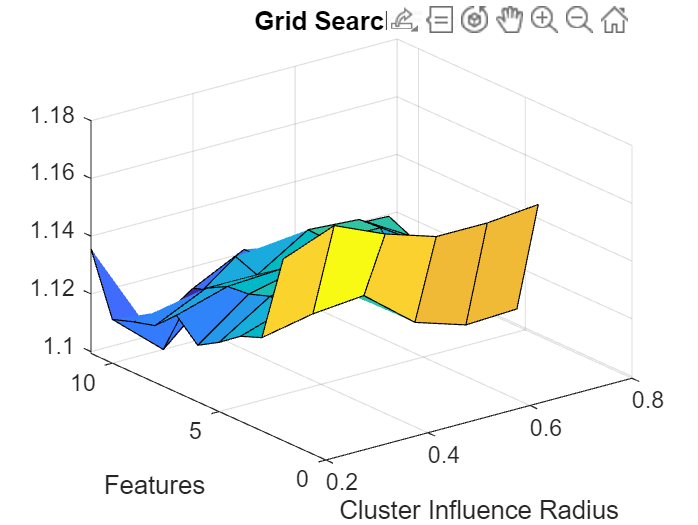

axesX = (0.2:0.1:0.7);
axesY = (2:11);
surf(axesX, axesY, crossValidationStats);
title('Grid Search Error')
xlabel('Cluster Influence Radius');
ylabel('Features')

## Optimal Configuration Selection

[optChar, optRadius] = find(crossValidationStats == min(crossValidationStats(:)));
optChar = optChar + 1;
optRadius = 0.1 * optRadius + 0.1;

%% Select final features in data
trnData = trnData(:, [ranks(1:optChar) size(data,2)]);
chkData = chkData(:, [ranks(1:optChar) size(data,2)]);
tstData = tstData(:, [ranks(1:optChar) size(data,2)]);

## Define Final Model - Class Based Subtractive Clusterring

% Build class clusters
[c1, sig1] = subclust(trnData(trnData(:, end) == 1,:), clusterRadius);
[c2, sig2] = subclust(trnData(trnData(:, end) == 2,:), clusterRadius);
[c3, sig3] = subclust(trnData(trnData(:, end) == 3,:), clusterRadius);
[c4, sig4] = subclust(trnData(trnData(:, end) == 4,:), clusterRadius);
[c5, sig5] = subclust(trnData(trnData(:, end) == 5,:), clusterRadius);
rulesNum = size(c1, 1) + size(c2, 1) + size(c3, 1) + size(c4, 1) + size(c5, 1);

% Construct FIS
initFIS = sugfis();

% Configure Input - Output
for k = 1:optChar
    initFIS = addInput(initFIS, [min(trnData(:,k)) max(trnData(:,k))], Name=sprintf("in%d", k));
end
initFIS = addOutput(initFIS, [min(data(:,end)) max(data(:,end))], Name='out1');

% Input Membership Functions
for m = 1:size(trnData, 2) - 1
    mfCounter = 0;
    for j = 1:size(c1,1)
        %initFIS = addmf(initFIS, 'input', m, '', 'gaussmf', [sig1(m) c1(j,m)]);
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig1(m) c1(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c1,1);
    for j = 1:size(c2,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig2(m) c2(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c2,1);
    for j = 1:size(c3,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig3(m) c3(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c3,1);
    for j = 1:size(c4,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig4(m) c4(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c4,1);
    for j = 1:size(c5,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig5(m) c5(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
end

% Output Membership Functions
params = [ones(1, size(c1,1)) ones(1, size(c2,1)) * 2 ...
    ones(1, size(c3,1)) * 3  ones(1, size(c4,1)) * 4  ...
    ones(1, size(c5,1)) * 5];
for m = 1:rulesNum
    initFIS = addMF(initFIS, 'out1', 'constant', params(m), Name=sprintf("mf_%d", m));
end

% FIS Rule Base
ruleList = zeros(rulesNum, size(trnData,2));
for m = 1:size(ruleList,1)
    ruleList(m,:) = m;
end
ruleList = [ruleList ones(rulesNum,2)];
initFIS = addRule(initFIS, ruleList);

anfisOptionsStruct = anfisOptions('InitialFIS', initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

## Train Model

[finalFIS, trainError, ~, valFIS, valError] = anfis(trnData, anfisOptionsStruct);

ANFIS info:
	Number of nodes: 145
	Number of linear parameters: 6
	Number of nonlinear parameters: 120
	Total number of parameters: 126
	Number of training data pairs: 7256
	Number of checking data pairs: 2272
	Number of fuzzy rules: 6


Start training ANFIS ...

1 	 1.10593 	 1.1352
2 	 1.09877 	 1.13009
3 	 1.09231 	 1.12482
4 	 1.08642 	 1.11763
Step size increases to 0.011000 after epoch 5.
5 	 1.08087 	 1.11658
6 	 1.07815 	 1.10897
7 	 1.07922 	 1.11656
8 	 1.07363 	 1.10439
9 	 1.07403 	 1.11274
Step size decreases to 0.009900 after epoch 10.
10 	 1.06999 	 1.10062
11 	 1.0696 	 1.10846
12 	 1.06606 	 1.09748
13 	 1.06653 	 1.10512
14 	 1.06431 	 1.09582
15 	 1.06434 	 1.10229
Step size decreases to 0.008910 after epoch 16.
16 	 1.06298 	 1.09463
17 	 1.06277 	 1.09982
18 	 1.06105 	 1.09341
19 	 1.06156 	 1.09787
20 	 1.06021 	 1.09274
21 	 1.06054 	 1.09633
Step size decreases to 0.008019 after epoch 22.
22 	 1.05941 	 1.09211
23 	 1.05962 	 1.09508
24 	 1.05798 	 1.09125
25 	


% Make Predictions & Round Data
rawY = evalfis(valFIS, tstData(:,1:end-1));
Y = round(rawY);
Y(Y < min(data(:,end))) = min(data(:,end));
Y(Y > max(data(:,end))) = max(data(:,end));

## Benchmarking and Graphing

#### Calculate performance metrics

[errorMat, accuracy, producerAcc, userAcc, k] = metrics(tstData, Y);

#### Stats, Learning Curves, Final MFs

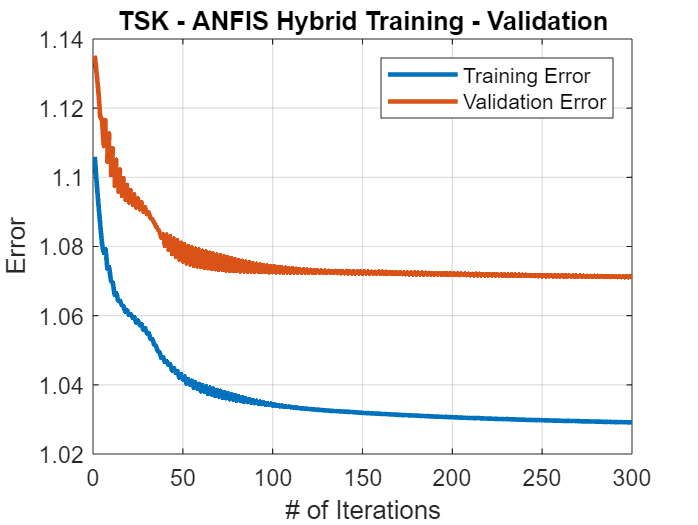

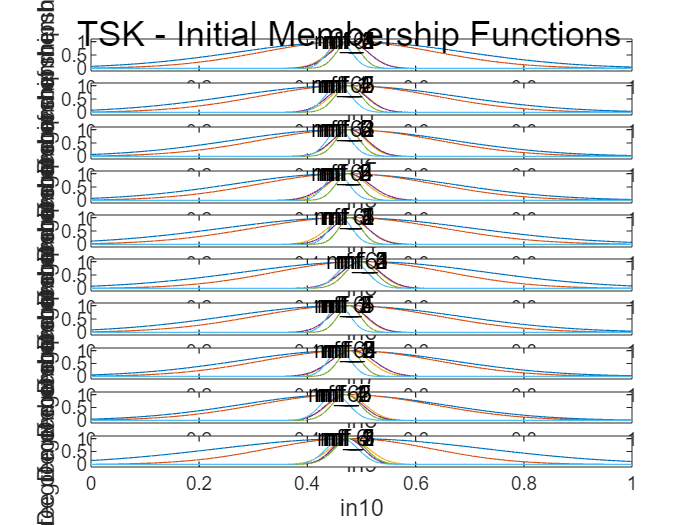

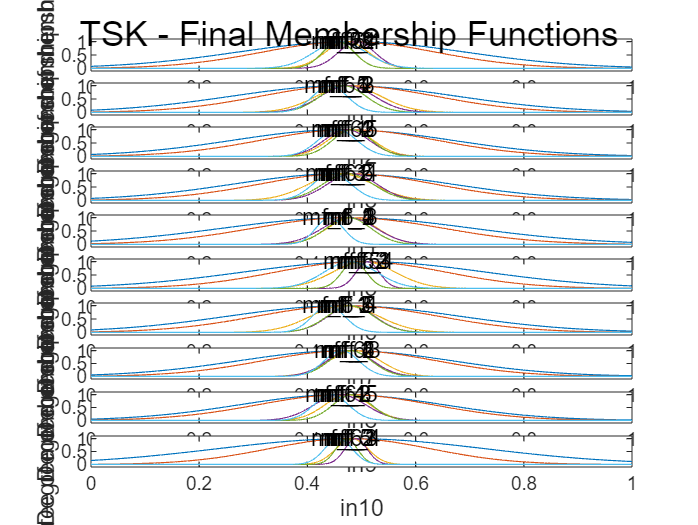

stats_graphs(valFIS, initFIS, chkData, trainError, valError);

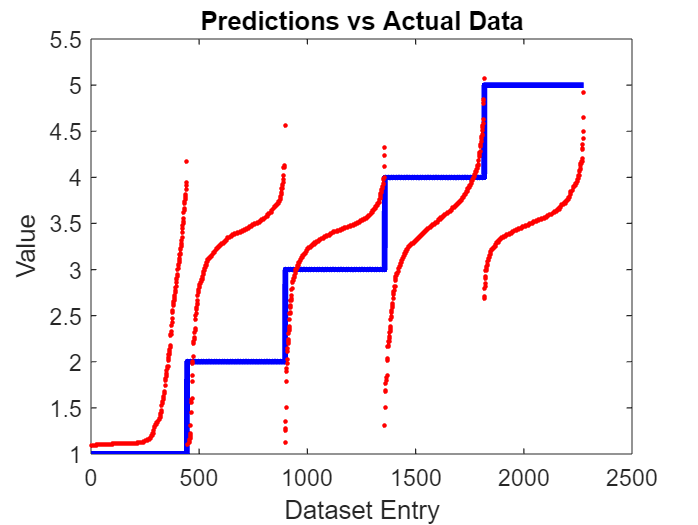


% Predictions - Data Plot (Raw Y)
tstY = [tstData(:, end) rawY];
tstY = sortrows(tstY);
figure
plot(tstY(:,1), '-b', 'LineWidth', 2.5)
hold on
plot(tstY(:,2), '.r')
title('Predictions vs Actual Data');
ylabel('Value');
xlabel('Dataset Entry');

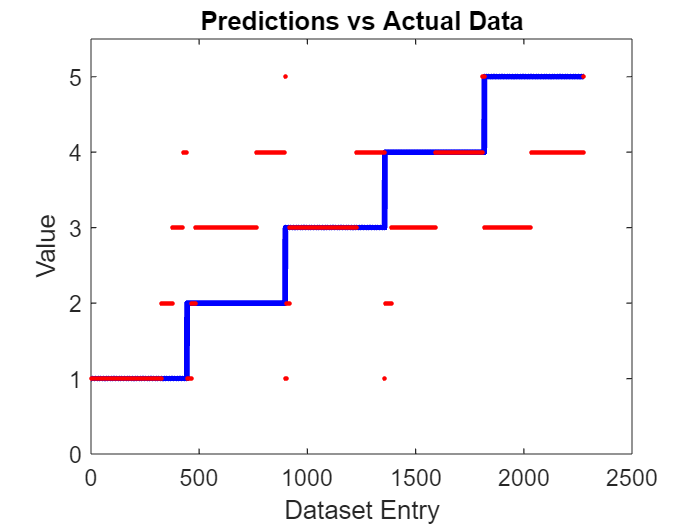

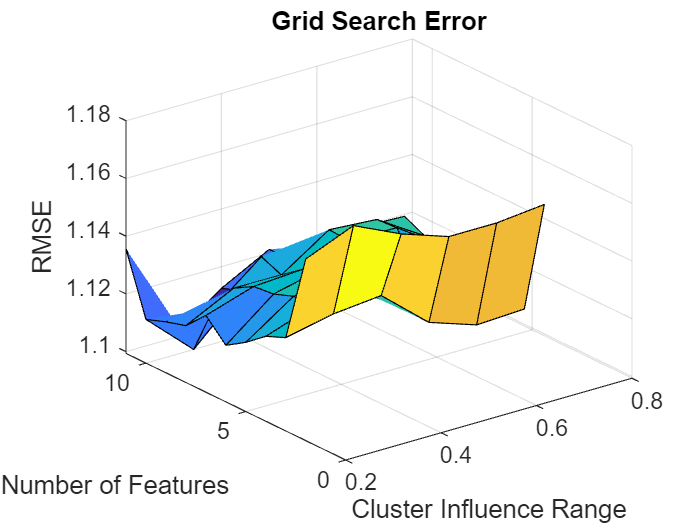


% Predictions - Data Plot (Rounded Y)
tstY = [tstData(:, end) Y];
tstY = sortrows(tstY);
figure
plot(tstY(:,1), '-b', 'LineWidth', 2.5)
hold on
plot(tstY(:,2), '.r')
title('Predictions vs Actual Data');
ylabel('Value');
xlabel('Dataset Entry');
ylim([0 5.5]);